% Pauli spin matrices

Ix = 0.5*[0  1;  1   0];

Iy = 0.5*[0 -1i; 1i  0];

Iz = 0.5*[1  0;  0  -1];

%I+ == Iplus is in another basis
Iplus = Ix + 1i*Iy; 
Iminus = Ix - 1i*Iy;


%Identity matrix
Ie = eye(2);

%These are supposed to be used for B, C... etc below. 
I1plus = kron(Iplus, Ie); %<  think this came out wrong should be [ 0 0; 1 0]>
I1minus = kron(Iminus, Ie);


% 0. double check magnitude of imaginary part of 
% 1. local oeprator, selective pulse evolution unde Ha, Hb (explicity)
% 2. start off antiparallel (do nothing) - evolve under H_B
% 3. Parallel evolution of H_B
% 4. spins >3 will have beating in dipolar interaction
% finite spins will never converge to zero (infinite spins)



I2plus = kron(Ie, Iplus);
I2minus = kron(Ie, Iminus);


I_1x = kron(Ix, Ie);
I_1y = kron(Iy, Ie);
I_1z = kron(Iz, Ie);

I_2x = kron(Ie, Ix);
I_2y = kron(Ie, Iy);
I_2z = kron(Ie, Iz);

%try1 = kron(Iplus, Ie)*(I_1y + I_2y)


syms omega_R t_R t
%assume(omega_R, 'real')
%assume(t_R, {'real', 'positive'})
assume(t, {'real', 'positive'})

% I may have defined these suckers straight up wrong..
%R_z_z = expm(1i*omega_R*t_R*(I_1z + I_2z));
%R_x_x = expm(1i*omega_R*t_R*(I_1x + I_2x));
%R_y_y = expm(1i*omega_R*t_R*(I_1y + I_2y));

%R_z_z = expm(1i*omega_R*t_R*(I_1z + I_2z));
R_x_x = expm(-1i*omega_R*t_R*(I_1y + I_2y));
%R_y_y = expm(1i*omega_R*t_R*(I_1y + I_2y));


syms k

%simplified with coupling strength k
H_A = I_1z*I_2z*k;
H_B = (I1plus*I2minus + I1minus*I2plus)*k;


syms H_Dipolar_rw [4 4] matrix
H_Dipolar = H_A + H_B;


syms rho_0 [4 4] matrix

rho_0_1 = I_1z;
%Startingoff antipolar
rho_0_2 = -I_2z;


rho_0 = rho_0_1 + rho_0_2;

Rotx = subs(R_x_x, omega_R*t_R, pi/2);

rho_rot1 = Rotx * rho_0 * Rotx';

H_dipolar_B = expm(-1i*t*H_B)

$$H\_dipolar\_B = \begin{array}{l} \left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & \sigma_{2} & \sigma_{1} & 0\\ 0 & \sigma_{1} & \sigma_{2} & 0\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{{\mathrm{e}}^{-k\,t\,\mathrm{i}}}{2}-\frac{{\mathrm{e}}^{k\,t\,\mathrm{i}}}{2}\\ \sigma_{2}=\frac{{\mathrm{e}}^{-k\,t\,\mathrm{i}}}{2}+\frac{{\mathrm{e}}^{k\,t\,\mathrm{i}}}{2} \end{array}$$



rho_HB(t) = H_dipolar_B*rho_rot1*H_dipolar_B'

$$rho\_HB(t) = \begin{array}{l} \left(\begin{array}{cccc} 0 & -\sigma_{1} & \sigma_{1} & 0\\ -\frac{{\mathrm{e}}^{k\,t\,\mathrm{i}}}{2} & 0 & 0 & \frac{{\mathrm{e}}^{k\,t\,\mathrm{i}}}{2}\\ \frac{{\mathrm{e}}^{k\,t\,\mathrm{i}}}{2} & 0 & 0 & -\frac{{\mathrm{e}}^{k\,t\,\mathrm{i}}}{2}\\ 0 & \sigma_{1} & -\sigma_{1} & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{{\mathrm{e}}^{-t\,\bar{k}\,\mathrm{i}}}{2} \end{array}$$



rho_rot2 = Rotx*rho_HB*Rotx'

$$rho\_rot2(t) = \begin{array}{l} \left(\begin{array}{cccc} 0 & 0 & 0 & 0\\ 0 & -\sigma_{1}-\frac{{\mathrm{e}}^{k\,t\,\mathrm{i}}}{2} & \sigma_{1}-\frac{{\mathrm{e}}^{k\,t\,\mathrm{i}}}{2} & 0\\ 0 & -\sigma_{1}+\frac{{\mathrm{e}}^{k\,t\,\mathrm{i}}}{2} & \sigma_{1}+\frac{{\mathrm{e}}^{k\,t\,\mathrm{i}}}{2} & 0\\ 0 & 0 & 0 & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{{\mathrm{e}}^{-t\,\bar{k}\,\mathrm{i}}}{2} \end{array}$$


rho_rot3 = Rotx*rho_rot2*Rotx'

$$rho\_rot3(t) = \begin{array}{l} \left(\begin{array}{cccc} 0 & \sigma_{1} & -\sigma_{1} & 0\\ \frac{{\mathrm{e}}^{k\,t\,\mathrm{i}}}{2} & 0 & 0 & -\frac{{\mathrm{e}}^{k\,t\,\mathrm{i}}}{2}\\ -\frac{{\mathrm{e}}^{k\,t\,\mathrm{i}}}{2} & 0 & 0 & \frac{{\mathrm{e}}^{k\,t\,\mathrm{i}}}{2}\\ 0 & -\sigma_{1} & \sigma_{1} & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{{\mathrm{e}}^{-t\,\bar{k}\,\mathrm{i}}}{2} \end{array}$$

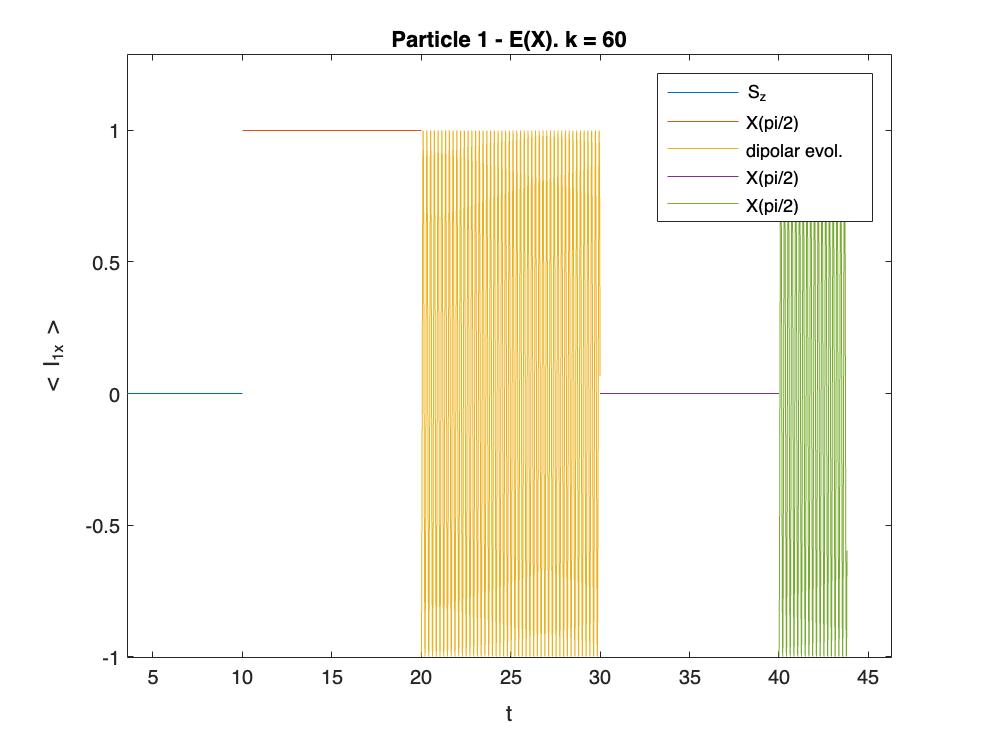

gimmeanotherplot = subs(trace(rho_HB*I_1z), k, 60);

gimmeanotherplot2 = subs(trace(rho_rot3*I_1z), k, 60);

fplot(trace(rho_0*I_1z), [0,10])
hold on
fplot(trace(rho_rot1*I_1z), [10, 20])
fplot(gimmeanotherplot, [20, 30])
rotation2subs = subs(trace(rho_rot2*I_1z), k, 60);
fplot(real(rotation2subs), [30, 40])
fplot(gimmeanotherplot2, [40, 50])
hold off
xlim([0 50])
xlabel('t')
ylim([-1 2])
ylabel('< I_1z >')
legend('S_z','X(pi/2)', 'dipolar evol.', 'X(pi/2)', 'X(pi/2)')
title('Particle 1 - E(Z). k = 60')

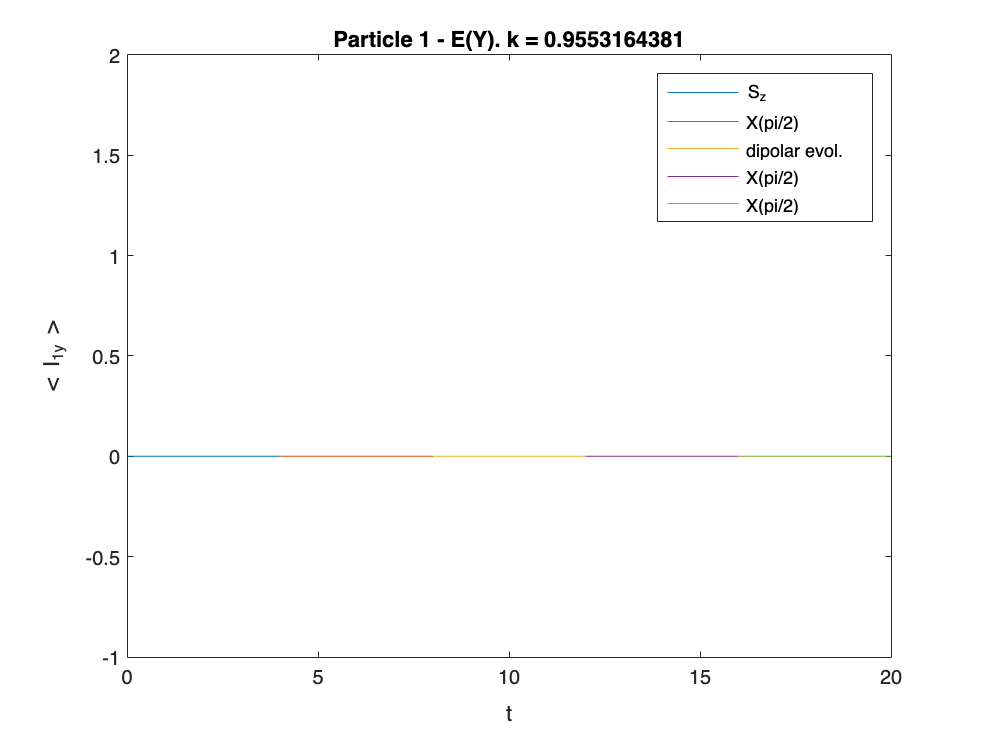

gimmeanotherplot3 = subs(trace(rho_HB*I_2z), k, 60);
gimmeanotherplot4 = subs(trace(rho_rot3*I_2z), k, 60);

fplot(trace(rho_0*I_2z), [0,10])
hold on
fplot(trace(rho_rot1*I_2z), [10, 20])
fplot(gimmeanotherplot3, [20, 30])
rotation2subs = subs(trace(rho_rot2*I_2z), k, 60);
fplot(real(rotation2subs), [30, 40])
fplot(gimmeanotherplot4, [40, 50])
hold off
xlim([0 50])
xlabel('t')
ylim([-1 2])
ylabel('< I_1z >')
legend('S_z','X(pi/2)', 'dipolar evol.', 'X(pi/2)', 'X(pi/2)')
title('Particle 2 - E(Z).')

plotrhodipolar = trace(rho_HB*(I_1z + I_2z));
plotrhodipolar = subs(plotrhodipolar, k, 60);

plotrot2 = real(trace(rho_rot2*(I_1z + I_2z)));
plotrot2 = subs(plotrot2, k, 60);
plotrot3z_1 = real(trace(rho_rot3*(I_1z + I_2z)));
plotrot3z_1 = subs(plotrot3z_1, k, 60);

fplot(real(trace(rho_0*(I_1z + I_2z))), [0,10])
hold on
fplot(real(trace(rho_rot1*(I_1z + I_2z))), [10, 20])
fplot(real(plotrhodipolar), [20, 30])
fplot(real(plotrot2), [30, 40])
fplot(real(plotrot3z_1), [40, 50])
hold off
xlim([0 50])
xlabel('t')
ylim([-1 2])
ylabel('< Sz >')
legend('S_z','X(pi/2)', 'dipolar evol.', 'X(pi/2)', 'X(pi/2)')
title('S(Z) I_1z + I_2z, k =60')

gimmeonemoredamnplot = subs(trace(rho_HB*I_1x), k, 60);

plotrot3z = trace(rho_rot3*I_1x);
plotrot3z = subs(plotrot3z, k, 60);
fplot(trace(rho_0*I_1x), [0,10])
hold on
fplot(trace(rho_rot1*I_1x), [10, 20])
fplot(real(gimmeonemoredamnplot), [20, 30])
fplot(trace(rho_rot2*I_1x), [30, 40])
fplot(real(plotrot3z), [40, 50])
hold off
xlim([0 50])
xlabel('t')
ylim([-1 2])
ylabel('< I_1x >')
legend('S_z','X(pi/2)', 'dipolar evol.', 'X(pi/2)', 'X(pi/2)')
title('Particle 1 - E(X). k = 60')

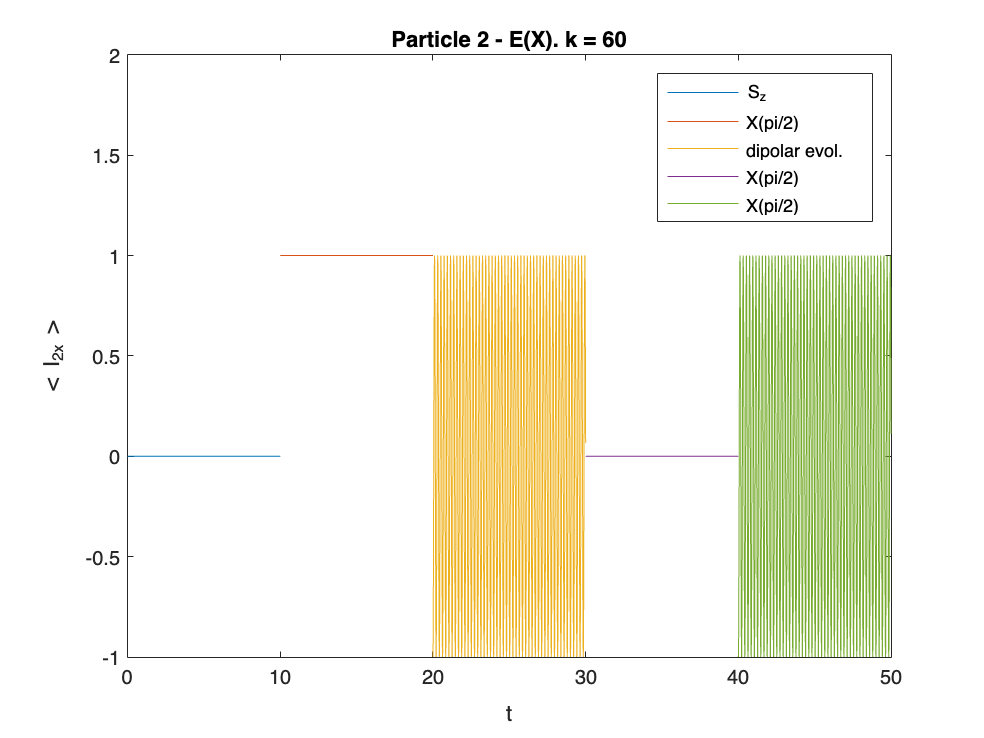

gimmeonemoredamnplot2 = subs(trace(rho_HB*I_2x),k, 60);

plotrot3z = trace(rho_rot3*I_2x);
plotrot3z = subs(plotrot3z, k, 60);
fplot(trace(rho_0*I_2x), [0,10])
hold on
fplot(trace(rho_rot1*I_2x), [10, 20])
fplot(real(gimmeonemoredamnplot2), [20, 30])
fplot(trace(rho_rot2*I_2x), [30, 40])
fplot(real(plotrot3z), [40, 50])
hold off
xlim([0 50])
xlabel('t')
ylim([-1 2])
ylabel('< I_2x >')
legend('S_z','X(pi/2)', 'dipolar evol.', 'X(pi/2)', 'X(pi/2)')
title('Particle 2 - E(X). k = 60')

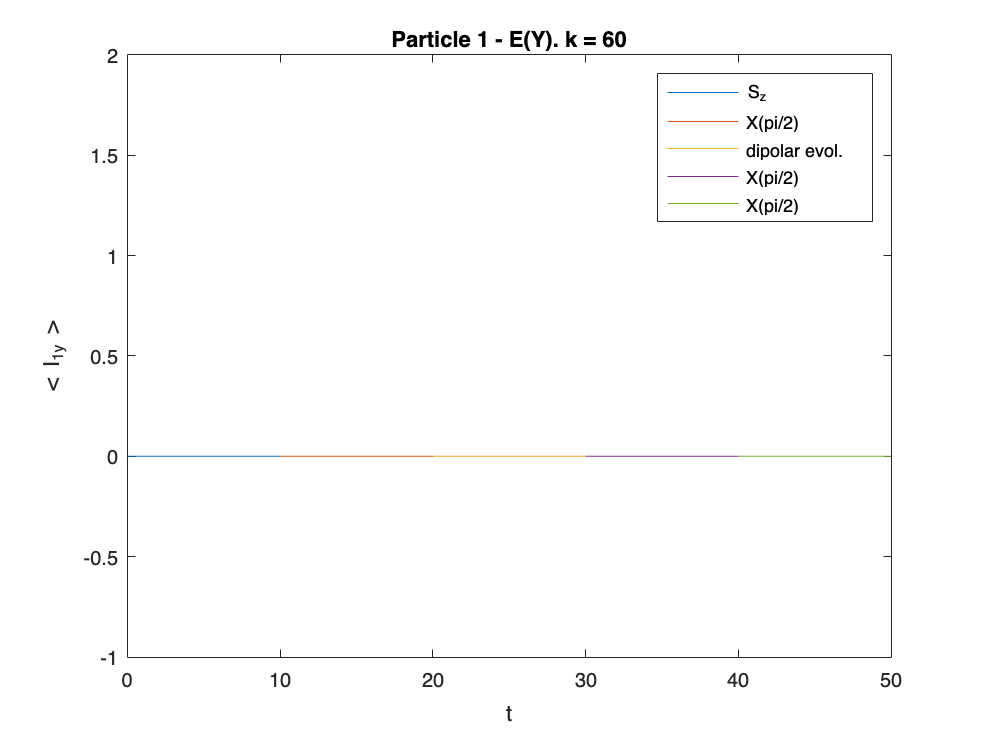

yplot1 = trace(rho_0*I_1y);
yplot2 = trace(rho_rot1*I_1y);
yplot3 = real(trace(rho_HB*I_1y));
yplot4 = real(trace(rho_rot2*I_1y));
yplot5 = real(trace(rho_rot3*I_1y));

yplot1 = subs(yplot1, k, 60);
yplot2 = subs(yplot2, k, 60);
yplot3 = subs(yplot3, k, 60);
yplot4 = subs(yplot4, k, 60);
yplot5 = subs(yplot5, k, 60);

%abs(trace(rho_rot1*I_1y))
%abs(trace(rho_AB_rw*I_1y))
fplot(yplot1, [0,10])
hold on
fplot(yplot2, [10, 20])
fplot(yplot3, [20, 30])
fplot(yplot4, [30, 40])
fplot(yplot5, [40, 50])
hold off
xlim([0 50])
xlabel('t')
ylim([-1 2])
ylabel('< I_1y >')
legend('S_z','X(pi/2)', 'dipolar evol.', 'X(pi/2)', 'X(pi/2)')
title('Particle 1 - E(Y). k = 60')

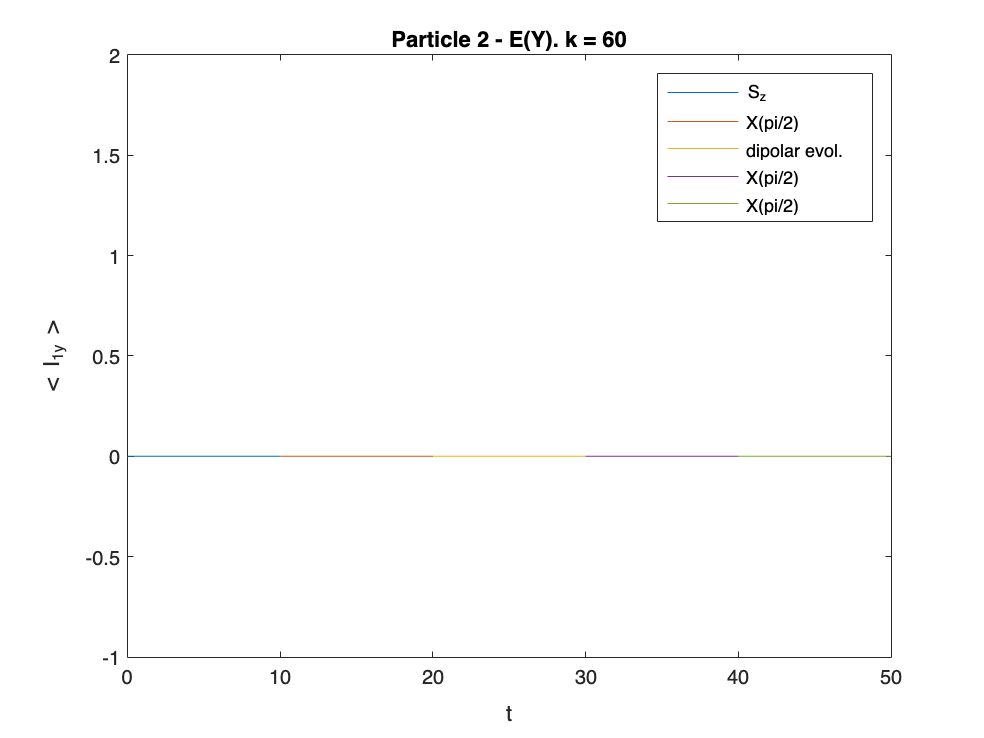

yplot1 = trace(rho_0*I_2y);
yplot2 = trace(rho_rot1*I_2y);
yplot3 = real(trace(rho_HB*I_2y));
yplot4 = real(trace(rho_rot2*I_2y));
yplot5 = real(trace(rho_rot3*I_2y));

yplot1 = subs(yplot1, k, 60);
yplot2 = subs(yplot2, k, 60);
yplot3 = subs(yplot3, k, 60);
yplot4 = subs(yplot4, k, 60);
yplot5 = subs(yplot5, k, 60);

%abs(trace(rho_rot1*I_1y))
%abs(trace(rho_AB_rw*I_1y))
fplot(yplot1, [0,10])
hold on
fplot(yplot2, [10, 20])
fplot(yplot3, [20, 30])
fplot(yplot4, [30, 40])
fplot(yplot5, [40, 50])
hold off
xlim([0 50])
xlabel('t')
ylim([-1 2])
ylabel('< I_1y >')
legend('S_z','X(pi/2)', 'dipolar evol.', 'X(pi/2)', 'X(pi/2)')
title('Particle 2 - E(Y). k = 60')

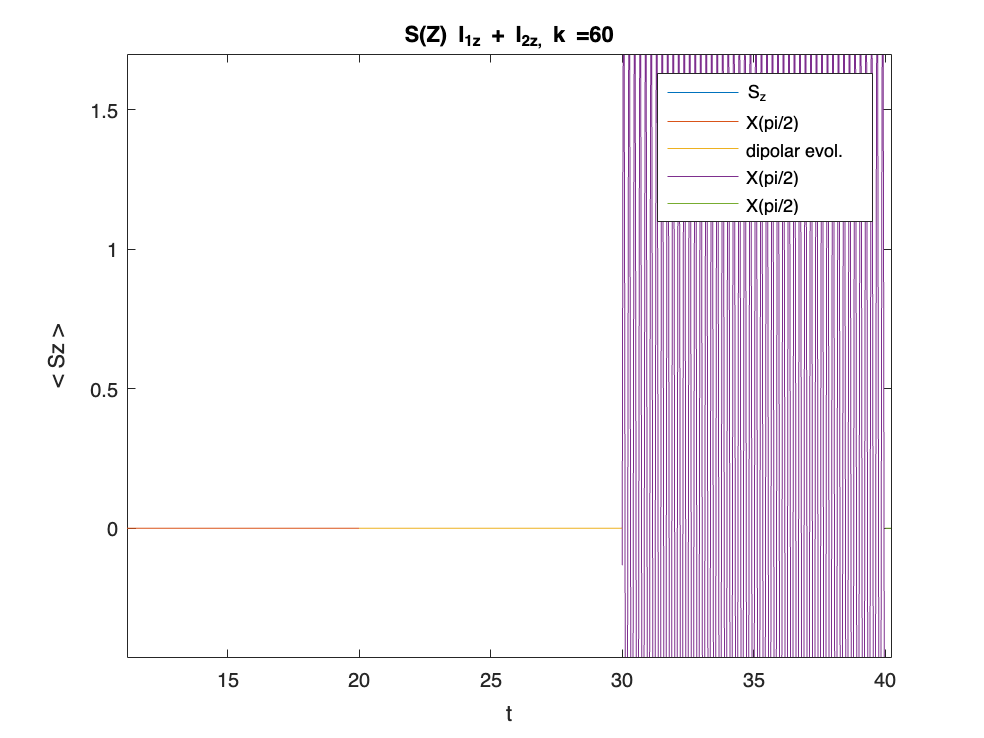

yplot1 = trace(rho_0*I_1y);
yplot2 = trace(rho_rot1*I_1y);
yplot3 = trace(rho_HB*I_1y);
yplot4 = trace(rho_rot2*I_1y);
yplot5 = trace(rho_rot3*I_1y);

yplot1 = subs(yplot1, k, 0.9553164381);
yplot2 = subs(yplot2, k, 0.9553164381);
yplot3 = subs(yplot3, k, 0.9553164381);
yplot4 = subs(yplot4, k, 0.9553164381);
yplot5 = subs(yplot5, k, 0.9553164381);

%abs(trace(rho_rot1*I_1y))
%abs(trace(rho_AB_rw*I_1y))
fplot(yplot1, [0,4])
hold on
fplot(yplot2, [4, 8])
fplot(yplot3, [8, 12])
fplot(yplot4, [12, 16])
fplot(yplot5, [16, 20])
hold off
xlim([0 20])
xlabel('t')
ylim([-1 2])
ylabel('< I_1y >')
legend('S_z','X(pi/2)', 'dipolar evol.', 'X(pi/2)', 'X(pi/2)')
title('Particle 1 - E(Y). k = 0.9553164381')